load 11_04_22\qualsis_data\3\UAS_Ollie_8ms0037.mat
data = UAS_Ollie_8ms0037;

trajectories = data.Trajectories.Unidentified.Data;

time = (1:1:data.Frames)/data.FrameRate;

axis = 3

axis = 3

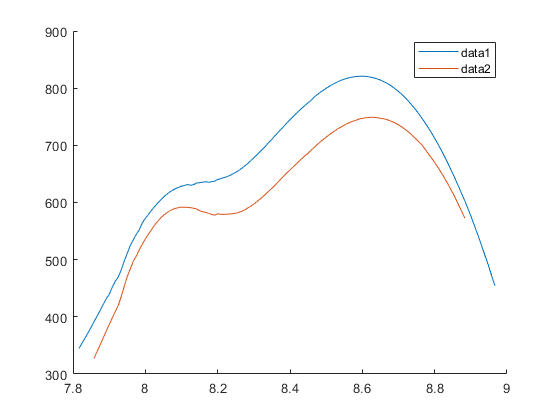

clf
hold on
% plot(time, squeeze(trajectories(2,3,:)))
% plot(time, squeeze(trajectories(3,3,:)))
plot(time, squeeze(trajectories(4,axis,:)))
plot(time, squeeze(trajectories(5,axis,:)))
hold off
legend

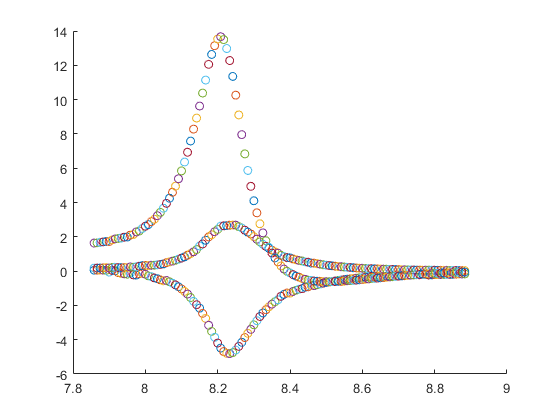

clf
hold on
for i = 1:length(time)
    try
        a = vrrotvec([squeeze(trajectories(4,1,i)), squeeze(trajectories(4,2,i)), squeeze(trajectories(4,3,i))],[squeeze(trajectories(5,1,i)), squeeze(trajectories(5,2,i)), squeeze(trajectories(5,3,i))]);
        b = quaternion(axang2quat(a));
        c = eulerd(b, 'ZYX', 'point');
        scatter(time(i), c(1))
    end
end
for i = 1:length(time)
    try
        a = vrrotvec([squeeze(trajectories(4,1,i)), squeeze(trajectories(4,2,i)), squeeze(trajectories(4,3,i))],[squeeze(trajectories(5,1,i)), squeeze(trajectories(5,2,i)), squeeze(trajectories(5,3,i))]);
        b = quaternion(axang2quat(a));
        c = eulerd(b, 'ZYX', 'point');
        scatter(time(i), c(2))
    end
end
for i = 1:length(time)
    try
        a = vrrotvec([squeeze(trajectories(4,1,i)), squeeze(trajectories(4,2,i)), squeeze(trajectories(4,3,i))],[squeeze(trajectories(5,1,i)), squeeze(trajectories(5,2,i)), squeeze(trajectories(5,3,i))]);
        b = quaternion(axang2quat(a));
        c = eulerd(b, 'ZYX', 'point');
        scatter(time(i), c(3))
    end
end
hold off

point1 = squeeze(trajectories(4,:,:));
point1 = point1(1:3, :);
point1(isnan(point1))=0;

point2 = squeeze(trajectories(5,:,:));
point2 = point2(1:3, :);
point2(isnan(point2))=0;

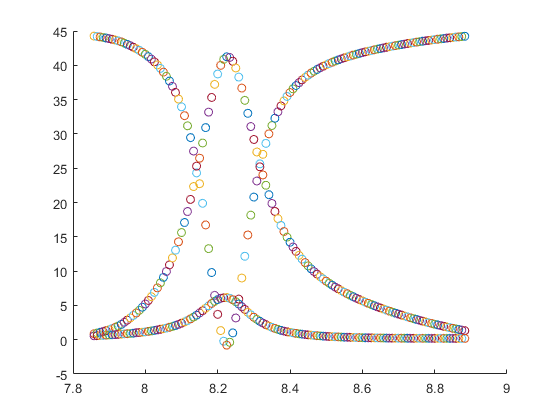

clf
hold on
for i = 1:length(time)
    a = point1(:,i);
    b = point2(:,i);
    if a ~= 0
        c = atand((a .* b) ./ (norm(a) * norm(b)));
        scatter(time(i), c(3))
        scatter(time(i), c(2))
        scatter(time(i), c(1))
    end
end
hold off

axis = 3

axis = 3

clf
diff3 = point1(3, :) - point2(3,:);
diff2 = point1(2, :) - point2(2,:);
diff1 = point1(1, :) - point2(1,:);

mag = vecnorm(point1(:,:) - point2(:,:))

mag = 	1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


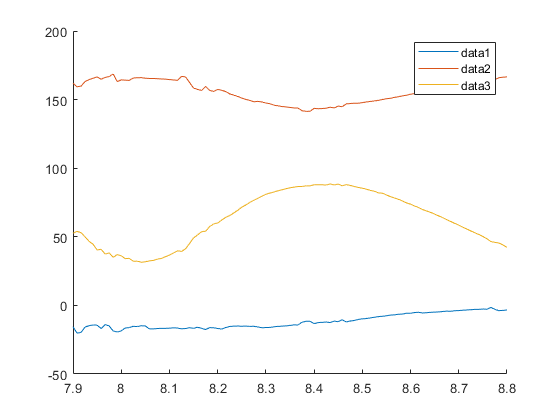

hold on
% plot(time, squeeze(trajectories(2,3,:)))
% plot(time, squeeze(trajectories(3,3,:)))
plot(time, diff1)
plot(time, diff2)
plot(time, diff3)
hold off
legend
xlim([7.9,8.8])

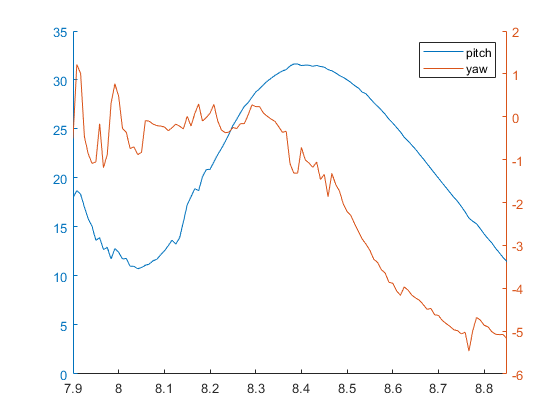

clf
hold on
xlim([7.9, 8.85])
yyaxis left
ylim([0,35])
plot(time,atand(diff3./diff2), 'DisplayName', "pitch")

yyaxis right
plot(time,atand(diff2./diff1)+84, 'DisplayName', "yaw")
hold off
legend